### Parámetros mecanismo 

%constantes
g = 9.81;

%Parámetros Mecánicos
m_m = 0.00339;    % Masa del Motor
m_b = 0.01056;    % Masa del brazo 
Lm = 0.135;     % Distancia hasta el motor 
Lb = 0.056;     % Distancia hasta el centro de masa

torqueB= m_b*Lb; %Torque genrado por el brazo al utilizar el centro de masa general
%torqueB1= m_b2*Lb2-m_b1*Lb1;

J_b = 0.00014;    % Momento de Inercia brazo 
J_m = 1/12*m_m*((11.4*10^-3)^2+(7*10^-3)^2);    % Momento de Inercia Motor
J = J_m + J_b;       % Momento de Inercia Total
betaF = 0.34*2*J;   % Coeficiente de fricción antes estaba en (0.5*2*Jb)
theta_ref = 80;      % Momento de Inercia Total 


Kf = 0.001191 %0.0015404 %Constante del motor (N/%PWM), El valor de Excel lo peta todo: 0.0015 (F/%PWM)

Kf = 0.0012

KPWM_ang = 0.7162;  % PWM/Angulo


## Linealización del sistema

Primero, la ecuación diferencial, es la siguiente:


$$\begin{array}{l}
\dot{x_1 } =x_2 \\
\dot{x_2 =-\frac{\beta }{J}x_2 -\frac{c}{J}\cdot \textrm{sen}\left(x_1 \right)+\frac{a}{J}u} 
\end{array}$$


syms u b c a x1 x2

g = 9.81; %Gravedad
m_m = 0.00339;    % Masa del Motor
m_b = 0.01056;    % Masa del brazo 
l_m = 0.135;     % Distancia hasta el motor 
l_b = 0.056;     % Distancia hasta el centro de masa
J_b = 0.00014;    % Momento de Inercia brazo 
J_m = 1/12*m_m*((11.4*10^-3)^2+(7*10^-3)^2);    % Momento de Inercia Motor
betaF = 0.34*2*J;   % Coeficiente de fricción antes estaba en (0.5*2*Jb)
theta_ref = 60;      % Momento de Inercia Total 
Kf = 0.001191 %0.0015404 %Constante del motor (N/%PWM)

Kf = 0.0012


%Asignar valores a variables simbolicas

J = J_m + J_b;       % Momento de Inercia Total

dx1 = x2

$$dx1 = x_{2}$$

dx2 = -(b/J)*x2 - (c/J)*sind(x1) + (a/J)*u

$$dx2 = \frac{36893488147419103232\,a\,u}{5166953535204153}-\frac{36893488147419103232\,b\,x_{2}}{5166953535204153}-\frac{36893488147419103232\,c\,\sin\left(\frac{\pi \,x_{1}}{180}\right)}{5166953535204153}$$

A = jacobian([dx1;dx2],[x1,x2])

$$A = \left(\begin{array}{cc} 0 & 1\\ -\frac{9223372036854775808\,\pi \,c\,\cos\left(\frac{\pi \,x_{1}}{180}\right)}{232512909084186885} & -\frac{36893488147419103232\,b}{5166953535204153} \end{array}\right)$$

B = jacobian([dx1;dx2],u)

$$B = \left(\begin{array}{c} 0\\ \frac{36893488147419103232\,a}{5166953535204153} \end{array}\right)$$





a = Kf*l_m;
b = betaF;
c = (l_b*m_b+l_m*m_m)*g;

u=theta_ref;
x1 = asind(u*a/c);
x2 = 0;

Aa = eval(A)%Matriz A del sistema linealizado

Aa =          0    1.0000
   -0.4464   -0.6800


Bb = eval(B)%Matriz B del sistema linealizado

Bb =          0
    1.1480


C = [1,0];

[num, den] = ss2tf(Aa,Bb,[1,0;0,1],zeros(2,1))

num =          0         0    1.1480
         0    1.1480         0


den =     1.0000    0.6800    0.4464


s=tf("s");
FuncionTransfer = num(1,3)/(den(1,1)*s^2 + den(1,2)*s + den(1,3))

FuncionTransfer =
 
          1.148
  ---------------------
  s^2 + 0.68 s + 0.4464
 
Continuous-time transfer function.
Model Properties


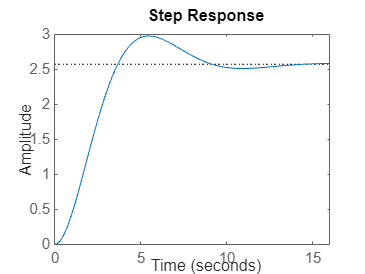

step(FuncionTransfer)


%Polos del sistema
polos_sistema = pole(FuncionTransfer)

polos_sistema =   -0.3400 + 0.5752i
  -0.3400 - 0.5752i


### SMC


%Cotas
J_max = J;
m_m_max = m_m;    
m_b_max = m_b;     
Lm_min = Lm;      
Lb_max = Lb;     
betaF_max = betaF;   
Kf_min = Kf;     


%parámetros simulink
Xr = pi/2;

X2_max = pi;

%beta
a = 1;
beta = (a*J_max-betaF)/(Lm_min*Kf_min)*X2_max  +  (m_m_max + Lb_max*m_b_max/Lm_min)*(g/Kf_min);
beta = ceil(beta);

%beta eq
a_eq = 1;
betaEq = (J_max/(Lm_min*Kf_min)-J/(Lm*Kf))   *   ((a-betaF/J)*X2_max   +   (Lb*m_b +Lm*m_m));
betaEq = ceil(betaEq);

#### Observador continuo

Determinar matriz de observabilidad

O = obsv(Aa, C)

O =      1     0
     0     1


rank(O);%Rango completo, si es observable

polos_deseados = polos_sistema %5 veces más rapidos que el sistema

polos_deseados =   -0.3400 + 0.5752i
  -0.3400 - 0.5752i


%polos_deseados= [-0.34 + 0.5*i , -0.34 - 0.5*i ]; %Tres veces más rapidos que el sistema
%[polos_deseados(1),polos_deseados(2)]
l = acker(Aa',C', polos_deseados)

l = 1.0e-15 *

    0.2220   -0.0555


**Observador discreto**

T_s = 0.01;

sis_estados= ss(Aa, Bb, C, 0); %Representación en espacio de estados del sistema 

sis_discreto = c2d(sis_estados, T_s);  % Discretización del sistema

A_d = sis_discreto.A;
B_d = sis_discreto.B;
C_d = sis_discreto.C;
D_d = sis_discreto.D;

polos_discretos = exp(polos_deseados * T_s)

polos_discretos =    0.9966 + 0.0057i
   0.9966 - 0.0057i




% Ganancias controlador discretas
L_d = (A_d') * l'

L_d = 1.0e-15 *

    0.2223
   -0.0529


### H_inf

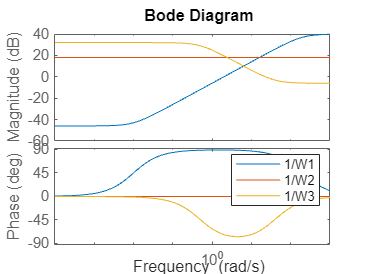


% Definir parámetros del filtro de desempeño
omega_b = 200;  % Frecuencia de cruce de banda deseada [rad/s]
omega_p = 1;   % Frecuencia a la que se atenúa
M = 100;        % Máxima sensibilidad permitida

% Definir el filtro de desempeño Wp
Wp = tf([1 omega_b], [M omega_p]);

% Definir parámetros del filtro de energía
a_u = 8;    % Límite de energía de la señal de control

% Definir el filtro de energía Wu
Wu = tf([1], [a_u]);

% Definir parámetros del filtro de sensibilidad
Ms = 0.5;       % Máxima sensibilidad permitida
omega_s = 1;  % Frecuencia de cruce de la sensibilidad
As = 0.025;     % Atenuación en bajas frecuencias

% Definir el filtro de sensibilidad Ws
Ws = tf([1/Ms omega_s], [1 omega_s/As]);


bode(1/Wp,1/Wu,1/Ws)
legend('1/W1','1/W2','1/W3')


W1 = Wp;
W2 = Wu;
W3 = Ws;
G = ss(Aa,Bb,C,0)

G =
 
  A = 
            x1       x2
   x1        0        1
   x2  -0.4464    -0.68
 
  B = 
          u1
   x1      0
   x2  1.148
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


P = augw(G, W1, W2, W3)

P =
 
  A = 
            x1       x2       x3       x4
   x1    -0.01        0       -1        0
   x2        0      -40        8        0
   x3        0        0        0        1
   x4        0        0  -0.4464    -0.68
 
  B = 
          u1     u2
   x1      1      0
   x2      0      0
   x3      0      0
   x4      0  1.148
 
  C = 
           x1      x2      x3      x4
   y1       2       0   -0.01       0
   y2       0       0       0       0
   y3       0  -9.875       2       0
   y4       0       0      -1       0
 
  D = 
          u1     u2
   y1   0.01      0
   y2      0  0.125
   y3      0      0
   y4      1      0
 
Input groups:       
    Name    Channels
     U1        1    
     U2        2    
                    
Output groups:      
    Name    Channels
     Y1      1,2,3  
     Y2        4    
                    
Continuous-time state-space model.



% Diseño del controlador H_infinito
ncont = 1;
nmeas = 1;
[K,CL,gamma,info] = hinfsyn(P,nmeas,ncont)

K =
 
  A = 
               x1          x2          x3          x4
   x1       -0.01  -4.864e-17  -1.974e-14  -4.158e-15
   x2   -6.61e-13         -40           8   7.089e-14
   x3   5.032e-12  -6.313e-15  -2.562e-12           1
   x4        3256      -3.617       -1658      -353.9
 
  B = 
               u1
   x1           1
   x2   1.893e-15
   x3  -1.441e-14
   x4   1.793e-15
 
  C = 
           x1      x2      x3      x4
   y1    2836  -3.151   -1444  -307.7
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


gamma = 1.0152

info =   hinfINFO with properties:

    gamma: 1.0152
        X: [4×4 double]
        Y: [4×4 double]
       Ku: [2.8361e+03 -3.1506 -1.4438e+03 -307.7036]
       Kw: [349.2281 -0.4381 -176.8268 -37.4558]
       Lx: [4×1 double]
       Lu: 0
     Preg: [5×2 ss]
       AS: [2×2 ss]


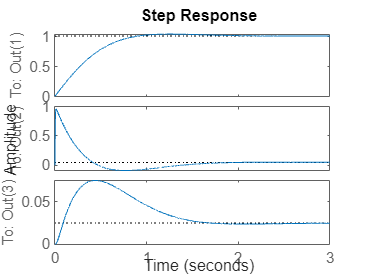

step(CL)

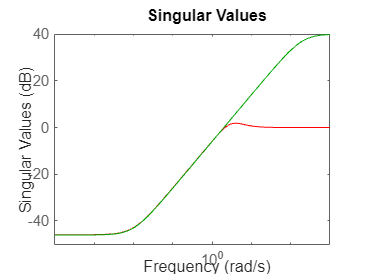

L = K*G;

S = feedback(1, L);

figure
sigma(S, 'r');
hold on
sigma(1/W1, 'g');

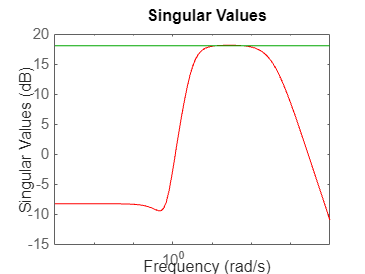

figure
sigma(S*K, 'r')
hold on
sigma(1/W2, 'g')

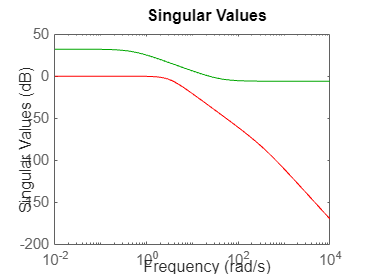

figure
T = feedback(L, 1);
sigma(T, 'r')
hold on
sigma(1/W3, 'g')
hold off

T_s = 0.01

T_s = 0.0100

h_inf = K

h_inf =
 
  A = 
               x1          x2          x3          x4
   x1       -0.01  -4.864e-17  -1.974e-14  -4.158e-15
   x2   -6.61e-13         -40           8   7.089e-14
   x3   5.032e-12  -6.313e-15  -2.562e-12           1
   x4        3256      -3.617       -1658      -353.9
 
  B = 
               u1
   x1           1
   x2   1.893e-15
   x3  -1.441e-14
   x4   1.793e-15
 
  C = 
           x1      x2      x3      x4
   y1    2836  -3.151   -1444  -307.7
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


h_inf_discreto = c2d(K, T_s)

h_inf_discreto =
 
  A = 
               x1          x2          x3          x4
   x1      0.9999   -1.35e-19   -5.48e-17  -1.155e-17
   x2    0.001933      0.6703     0.06495   0.0001386
   x3     0.06607  -6.266e-05      0.9664     0.00268
   x4       8.726   -0.007188      -4.444     0.01772
 
  B = 
              u1
   x1       0.01
   x2  5.611e-06
   x3  0.0002697
   x4    0.06607
 
  C = 
           x1      x2      x3      x4
   y1    2836  -3.151   -1444  -307.7
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


sis_discreto = c2d(sis_estados, T_s);  % Discretización del sistema